n=10;
mypath = rand(n,2);
m = cumsum(mypath);
mout = m./m(end,:);    
load("X1.mat");
load("Y1.mat");
load("curve_one.mat");
% disp(curve_one)
% plot(X1,Y1)


### **Breakdown of 9X21 Grid**

**Three vertical sections**: subject, verb, object

**Three horizontal sections**: prefix, affix, suffix

### Variables to keep at all points 

- Current X, Y, pressure and time ***Done***

- x and y position vectors (1-9 and 1-21) ***Done***

- pressure vector (1-3) ***Done***

- direction of movement (1-8) 

**Functions needed**

- Randomly choose origin in the prefix column 

-     Choose starting x(1-3)

-     Choose starting y(1-3)

- Randomly choose functions

- Randomly change direction

-     Directions allowed to move (N(1) to NW(8))    

- Randomly change pressure

- Randomly change speed 

**Move n= 1, 2, 3 or 4 units**      

### Subject (1,1 to 9,7)

% Hyperparameters
% k - scale of range of probabilities that forward direction can take
% n - skewness of distribution of direction probabilities
% origin_probabs - probability weights for choosing origin 
% propogation_probabs - probability weights for propogation 1 2 or 3 units at step
% 


% x0=[0.9 0.5 0.6 0.25 0.15 0.25 0.5 0.25 0.4 0.4 0.2];
% ratio = calculateGeneratorPerformance(x0);
% options = optimset('PlotFcns',@optimplotfval);
% x=fminsearch(@calculateGeneratorPerformance,x0,options)

% [gross_avg_data_density, gross_avg_ang_vel, gross_avg_dist_corner]=calculateGeneratorPerformance(0.9,0.5,0.6, 0.25, 0.15, 0.25, 0.5, 0.25, 0.4, 0.4, 0.2)

n=optimvar("n","LowerBound",0,"UpperBound",1);
k=optimvar("k","LowerBound",0,"UpperBound",1);
Xop1=optimvar("Xop1","LowerBound",0.001,"UpperBound",1);
Xop2=optimvar("Xop2","LowerBound",0.001,"UpperBound",1);
Xop3=optimvar("Xop3","LowerBound",0.001,"UpperBound",1);
Yop1=optimvar("Yop1","LowerBound",0.001,"UpperBound",1);
Yop2=optimvar("Yop2","LowerBound",0.001,"UpperBound",1);
Yop3=optimvar("Yop3","LowerBound",0.001,"UpperBound",1);
pp1=optimvar("pp1","LowerBound",0.001,"UpperBound",1);
pp2=optimvar("pp2","LowerBound",0.001,"UpperBound",1);
pp3=optimvar("pp3","LowerBound",0.001,"UpperBound",1);
[data_density, ang_vel, dist_corner]=fcn2optimexpr(@calculateGeneratorPerformance,n,k,Xop1,Xop2,Xop3,Yop1,Yop2,Yop3,pp1,pp2,pp3);
prob=optimproblem();
prob.Objective.data_density=data_density;
prob.Objective.ang_vel=ang_vel;
prob.Objective.dist_corner=dist_corner;
prob.ObjectiveSense.data_density="maximize";
prob.ObjectiveSense.ang_vel="minimize";
prob.ObjectiveSense.dist_corner="minimize";
prob.Constraints.cons1=Xop1+Xop2+Xop3==1;
prob.Constraints.cons2=Yop1+Yop2+Yop3==1;
prob.Constraints.cons3=pp1+pp2+pp3==1;
prob.Constraints.cons4=Xop1*Xop2*Xop3>=0.03;
prob.Constraints.cons5=Yop1*Yop2*Yop3>=0.03;
prob.Constraints.cons6=pp1*pp2*pp3>=0.03;
show(prob);


  OptimizationProblem : 

	Solve for:
       Xop1, Xop2, Xop3, Yop1, Yop2, Yop3, k, n, pp1, pp2, pp3

	maximize data_density:
       [argout,~,~] = calculateGeneratorPerformance(n, k, Xop1, Xop2, Xop3,
     Yop1, Yop2, Yop3, pp1, pp2, pp3)

	minimize ang_vel:
       [~,argout,~] = calculateGeneratorPerformance(n, k, Xop1, Xop2, Xop3,
     Yop1, Yop2, Yop3, pp1, pp2, pp3)

	minimize dist_corner:
       [~,~,argout] = calculateGeneratorPerformance(n, k, Xop1, Xop2, Xop3,
     Yop1, Yop2, Yop3, pp1, pp2, pp3)



	subject to cons1:
       Xop1 + Xop2 + Xop3 == 1

	subject to cons2:
       Yop1 + Yop2 + Yop3 == 1

	subject to cons3:
       pp1 + pp2 + pp3 == 1

	subject to cons4:
       ((Xop1 .* Xop2) .* Xop3) >= 0.03

	subject to cons5:
       ((Yop1 .* Yop2) 

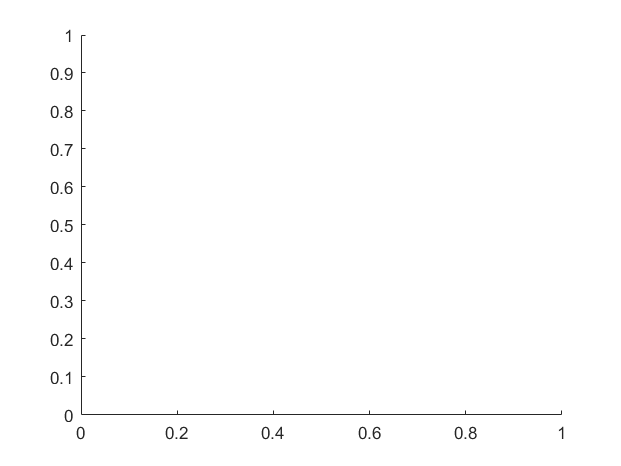

Solving problem using gamultiobj.

Diagnostic information:
Multi-objective function: @(x)fun(x,extraParams)
Nonlinear constraint function: @(x)fun(x,extraParams)
11 Variable(s)
3 Nonlinear inequality constraint(s)
3 Linear equality constraint(s)

Options:
CreationFcn:       @gacreationlinearfeasible
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible
PopulationSize:    50
Generations:       80
InitialPopulation: 10-by-11
Display:           'diagnose'
PlotFcns:          { @gaplotpareto }
End of diagnostic information.



                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1            51                 1                 1
    2           101         0.0221922           0.89208
    3           151         0.0232849          0.852268
    4           201         0.0108047          0.939803
    5           251         0.0291636          0.869659
    6           301         0.0189324          0.827676
    7           351         0.0218952          0.115385
    8           401         0.0188747          0.100468
    9           451         0.0126377          0.878235
   10           501         0.0233027          0.122222
   11           551          0.025821          0.117956
   12           601         0.0279234           0.12075
   13           651         0.0259902          0.115098
   14           701         0.0243229          0.111857
   15           751         0.0222698         0.0949407
   16           801         0.0217715     

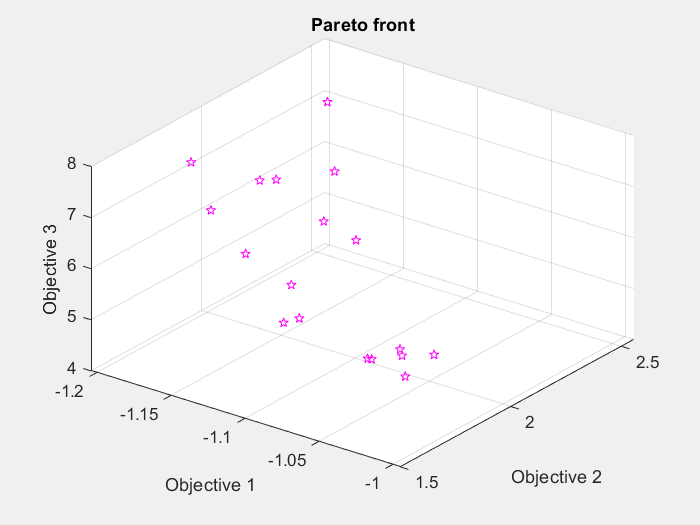

sol =   1×18 OptimizationValues vector with properties:

   Variables properties:
            Xop1: [0.2718 0.2673 0.2730 0.2652 0.2729 0.2637 0.2431 0.2431 0.2502 0.2599 0.2666 0.2685 0.2661 0.2680 0.2666 0.2688 0.2641 0.2718]
            Xop2: [0.2451 0.2408 0.2467 0.2537 0.2467 0.2594 0.2793 0.2793 0.2679 0.2604 0.2574 0.2420 0.2480 0.2416 0.2574 0.2423 0.2510 0.2454]
            Xop3: [0.4831 0.4920 0.4803 0.4811 0.4804 0.4769 0.4777 0.4777 0.4819 0.4797 0.4760 0.4896 0.4860 0.4904 0.4760 0.4890 0.4849 0.4828]
            Yop1: [0.2622 0.2728 0.2626 0.2681 0.2646 0.2688 0.2807 0.2807 0.2784 0.2722 0.2697 0.2702 0.2708 0.2721 0.2697 0.2695 0.2717 0.2650]
            Yop2: [0.2645 0.2632 0.2680 0.2658 0.2696 0.2667 0.2625 0.2625 0.2627 0.2643 0.2639 0.2640 0.2652 0.2650 0.2639 0.2641 0.2644 0.2673]
            Yop3: [0.4733 0.4639 0.4694 0.4660 0.4657 0.4645 0.4567 0.4567 0.45

fval =     1.0373    1.0775    0.9945    1.0673    1.1465    1.1922    1.2017    1.1839    1.1523    1.1779    1.2038    1.0019    1.0934    1.1455    1.1269    1.0454    1.1370    1.1131
    1.6369    2.0530    1.5208    1.8563    1.6590    2.2610    2.5564    2.4698    2.3548    2.0906    1.9531    1.5559    1.7034    2.1632    1.8567    1.9922    1.7522    1.7991
    5.4125    4.2516    5.7204    4.6135    7.2824    6.0500    6.7839    5.7905    4.9997    6.5643    7.0112    5.9803    5.5391    5.8832    4.7912    4.5763    6.2952    5.7916


% init_sol=[0.2639 0.2376 0.4985 0.2807 0.2625 0.4567 0.1345 0.3291 0.2571 0.2313 0.5115,...
%           0.2638 0.2376 0.4985 0.2801 0.2628 0.4571 0.1344 0.3294 0.2568 0.2317 0.5055 ]
options = optimoptions('gamultiobj',...
    'PlotFcn',{@gaplotpareto},...
    'MaxGenerations',80,...
    'PopulationSize',50,...
    'InitialPopulationMatrix',init_sol,...
    'Display','diagnose');
start = optimvalues(prob,"Xop1", [0.2639 0.2777 0.2949 0.2837 0.2638 0.2845 0.2942 0.2903 0.2853 0.2696],...
    "Xop2", [0.2376 0.2497 0.2691 0.2564 0.2376 0.2565 0.2663 0.2644 0.2558 0.2430],...
    "Xop3", [0.4985 0.4726 0.4360 0.4599 0.4985 0.4590 0.4395 0.4453 0.4590 0.4875],...
    "Yop1",[0.2807 0.2415 0.2249 0.2357 0.2801 0.2229 0.2636 0.2331 0.2146 0.2669],...
    "Yop2", [0.2625 0.2629 0.2872 0.2713 0.2628 0.2631 0.2260 0.2836 0.2652 0.2621],...
    "Yop3", [0.4567 0.4957 0.4879 0.4930 0.4571 0.5140 0.5104 0.4833 0.5203 0.4710],...
    "k", [0.1345 0.1284 0.1256 0.1275 0.1344 0.1270 0.1301 0.1269 0.1259 0.1325],...
    "n",[0.3291 0.3539 0.3259 0.3442 0.3294 0.3488 0.3210 0.3264 0.3542 0.3333],...
    "pp1", [0.2571 0.2465 0.2589 0.2517 0.2568 0.2472 0.2525 0.2586 0.2470 0.2542],...
    "pp2",[0.2313 0.2395 0.2329 0.2367 0.2317 0.2473 0.2367 0.2327 0.2508 0.2348],...
    "pp3",[0.5115 0.5140 0.5085 0.5116 0.5115 0.5055 0.5108 0.5089 0.5022 0.5111]);
[sol,fval] = solve(prob,start,"Solver","gamultiobj","Options",options)

% sol = [0.2903 0.2644 0.4453 0.2331 0.2836 0.4833 0.1269 0.3264 0.2586 0.2327 0.5089]
% Xop1=sol(1);
% Xop2=sol(2);
% Xop3=sol(3);
% Yop1=sol(4);
% Yop2=sol(5);
% Yop3=sol(6);
% k=sol(7);
% n=sol(8);
% pp1=sol(9);
% pp2=sol(10);
% pp3=sol(11);
% X_origin_probabs = [Xop1 Xop2 Xop3];
% Y_origin_probabs = [Yop1 Yop2 Yop3];
% switch_pressure_probabilities= [];
% switch_speed_probabilites=[];
% propagation_probabilities = [pp1 pp2 pp3];
% [X1_positions, Y1_positions, dir_sequence1, dist_corner1]=generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
% length_1 = length(dir_sequence1)
% data_density1=data_density_rel(X1_positions,Y1_positions)
% average_angular_vel1 = angular_vel_avg(dir_sequence1)
% ratio1= data_density1/average_angular_vel1
% 
% [X2_positions, Y2_positions, dir_sequence2, dist_corner2]=generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
% length_2 = length(dir_sequence2)
% data_density2=data_density_rel(X2_positions,Y2_positions)
% average_angular_vel2 = angular_vel_avg(dir_sequence2)
% ratio2= data_density2/average_angular_vel2
% 
% gestalt_distance = gestaltDistance(char(strjoin(string(dir_sequence1))),char(strjoin(string(dir_sequence1))))
% frechet_distance = frechet(X1_positions',Y1_positions',X2_positions',Y2_positions')
% distance1=dist_corner1
% distance2=dist_corner2
% %Plot stroke
% plot(X1_positions,Y1_positions,'LineWidth',3)
% hold on 
% plot(X2_positions,Y2_positions,'LineWidth',3)
% xlim([1 9])
% ylim([1 21])
% set(gca, 'YDir','reverse')
% grid on
% pbaspect([1 1 1])
% daspect([1 1 1])
% hold off


% function f=calculateGeneratorPerformance(x)
% n=x(1);
% k=x(2);
% Xop1=x(3);
% Xop2=x(4);
% Xop3=x(5);
% Yop1=x(6);
% Yop2=x(7);
% Yop3=x(8);
% pp1=x(9);
% pp2=x(10);
% pp3=x(11);



function [gross_avg_data_density, gross_avg_ang_vel, gross_avg_dist_corner]=calculateGeneratorPerformance(n,k,Xop1,Xop2,Xop3,Yop1,Yop2,Yop3,pp1,pp2,pp3)
X_origin_probabs = [Xop1 Xop2 Xop3];
Y_origin_probabs = [Yop1 Yop2 Yop3];
propagation_probabilities = [pp1 pp2 pp3];
switch_pressure_probabilities = [];
switch_speed_probabilites = [];
generator_avg_ang_vel=[];
generator_avg_data_density=[];
generator_avg_dist_corner = [];
for iter=1:30
    [X_positions, Y_positions, dir_sequence, dist_corner] = generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
    data_density=data_density_rel(X_positions,Y_positions);
    average_angular_vel = angular_vel_avg(dir_sequence);
    generator_avg_ang_vel(end+1)=average_angular_vel;
    generator_avg_data_density(end+1)=data_density;
    generator_avg_dist_corner(end+1)=dist_corner;
%     scatter(data_density,average_angular_vel,50*ratio,"filled")
%     xlabel('data density')
%     ylabel('avg ang vel')
    hold on
end
    hold off
    gross_avg_data_density=sum(generator_avg_data_density)/20;
    gross_avg_ang_vel=sum(generator_avg_ang_vel)/20;
    gross_avg_dist_corner=sum(generator_avg_dist_corner)/20;
end



function [X_positions, Y_positions, dir_sequence, dist_corner]=generateRandomGesture(X_origin_probabs, Y_origin_probabs,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites )

s = RandStream('mlfg6331_64','Seed','shuffle');
X_positions = [];
Y_positions = [];
pressure_variation = [];
pressure_current = 0;
time_frame = 0;

% Choose origin
% Choose starting x and y
X_origin = randsample(s,1:3,1,true,X_origin_probabs);
Y_origin = randsample(s,[1 2 3],1,true,Y_origin_probabs);
time_frame = 1;
X_positions(end+1)=X_origin;
Y_positions(end+1)=Y_origin;

pressure_current = 1;
pressure_variation(end+1)=pressure_current;
prop_dir = 0;
dir_sequence = [];
m=1; reached_edge=0; hitting_edge=0;
dist_corner=Inf;
while m<=15 && reached_edge==0 && hitting_edge==0
    m=m+1;
    % Randomly choose propogation length
    % Propogate 1-4 units
    dir = [1 2 3 4 5 6 7 8];
    prop_len = randsample(s,1:3,1,true,propagation_probabilities);
    
    % Calculate possible directions
    % -Cannot cross left edge
    if X_positions(end)-prop_len<=0
        dir(dir==6 | dir==7 | dir==8) = [];
    end
    % -Cannot cross top edge
    if Y_positions(end)-prop_len<=0
        dir(dir==8 | dir==1 | dir==2) = [];
    end
    % -Cannot cross right edge
    if X_positions(end)+prop_len>=10
        dir(dir==2 | dir==3 | dir==4) = [];
%         disp("hitting right edge, breaking")
           hitting_edge=1;
    end
    % -Cannot cross bottom edge
    if Y_positions(end)+prop_len>=8
        dir(dir==6 | dir==5 | dir==4) = [];
    end
    
    % Select direction randomly
    last_dir = prop_dir;
    dir_len = length(dir);
    sz = size(dir);
    dir_probabs = ones(sz)*(1/dir_len);
    prop_dir = randsample(s,dir,1,true,dir_probabs_gen(dir,k,n));
    
    iter = 1;
    % Propogate
    while iter<=prop_len && reached_edge==0
        iter = iter+1;
        time_frame = time_frame + 1;
        if prop_dir<5 && prop_dir>1
            X_positions(end+1)=X_positions(end)+1;
        end
        if prop_dir>5 && prop_dir<9
            X_positions(end+1)=X_positions(end)-1;
        end
        if prop_dir<7 && prop_dir>3
            Y_positions(end+1)=Y_positions(end)+1;
        end
        if prop_dir<3 || prop_dir>7
            Y_positions(end+1)=Y_positions(end)-1;
        end
        if prop_dir==1 || prop_dir==5
            X_positions(end+1)=X_positions(end);
        end
        if prop_dir==7 || prop_dir==3
            Y_positions(end+1)=Y_positions(end);
        end
        dir_sequence(end+1)=prop_dir;
        pressure_variation(end+1)=pressure_current;
        if X_positions(end)==9
%             disp("reached X=9 breaking")
            reached_edge=1;
        end
    end
    dist_corner=norm([X_positions(end)-9 Y_positions(end)-7]);
end
end


% Randomly Choose dynamic variations                      Probabilities
% 0 : no change                                               0.7
% 1 : change pressure randomly 1 step up or down              0.2
% 2 : change speed 1 tempo randomly                           0.1


function y = data_density_rel(X_positions,Y_positions)
    gesture = zeros(9,7);
    for n=1:length(X_positions)
        gesture(Y_positions(n),X_positions(n))=1;
    end
    y = entropy(mat2gray(gesture)) ;
end

function y = dir_probabs_gen(dir,k,n)
% k=scale for range of probability for 3 between 2/7 and 1 (0-1)
% m=slope of distribution
m=rand*(1-n)+n;
min_probab_3 = (k*3 + 2)/7;
probab_3 = rand*(1-min_probab_3)+min_probab_3;
probabs=[];
m = m*min_probab_3/4;
% index= [1 2 3 4 5 6 7 8]
for i=1:length(dir)
    if dir(i)==4
        probabs(end+1)=probab_3;
    end
    if dir(i)==3 || dir(i)==5
        probabs(end+1)=probab_3-m;
    end
    if dir(i)==2 || dir(i)==6
        probabs(end+1)=probab_3-2*m;
    end
    if dir(i)==7 || dir(i)==1
        probabs(end+1)=probab_3-3*m;
    end
    if dir(i)==8
        probabs(end+1)=probab_3-4*m;
    end
end
y=probabs;
end

function y = gestaltDistance(X,Y)
total_len = length(X)+length(Y);
endloop = 0;
K=0;
while endloop==0
   [substr] = commonsubstring(char(X),char(Y));
   if isempty(substr)
       endloop=1;
   end
   if size(substr,1)>1
        for i=1:size(substr,1)
            K=K+length(substr(i,:));
            X=erase(X,substr(i,:));
            Y=erase(Y,substr(i,:));
        end
   else
       K=K+length(substr);
       X=erase(X,substr);
       Y=erase(Y,substr);
   end
end
y=(2*K)/(total_len);
end


function y = angular_vel_avg(X)
% Angular Velocity: rate of change of angle
% final angle - initial angle
% increase: (final - initial) * 45'
% decrease: abs(final - initial)* 45'
% ((b - a) + len) % len), where a is the "from" index, b is the "to" index, and len is the length of the array
    dirs = [1 2 3 4 5 6 7 8];
    av=0;
    for i=2:length(X)
        b=find(dirs==X(i));
        a=find(dirs==X(i-1));
        diff= mod(((b - a) + 8), 8);
        if diff<0
            disp("negative diff")
        end
        av=av+diff;
    end
    y=av/length(X);
end